clear all; clc; close all;

% Definizione dei parametri globali
global lunghezza_passo raggio_curva num_iterazioni punti direzioni contatore distanza_minima adjacency_matrix

% Load map from a. mat file
data = load('map_straight_with_roundabout.mat');
% data = load('test/Files_mat/maps_5_1.mat');  % Sostituisci 'nome_file_mappa.mat' con il tuo percorso e nome del file

% Check available fields in 'data' structure
disp(fieldnames(data));

    {'map_straight_with_roundabout'}



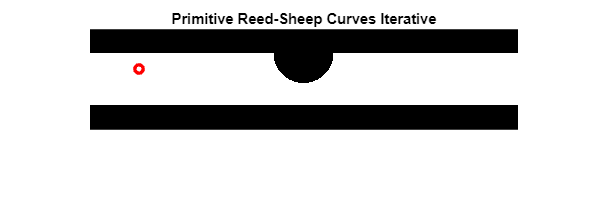


% Extract map from data structure
map = data.map_straight_with_roundabout;
% map = data.invertedImage;

% Definizione dei parametri
lunghezza_passo = 30.0; % Lunghezza del passo in avanti
raggio_curva = 20.0; % Raggio di curvatura per le curve a destra e sinistra
num_iterazioni = 3; % Numero di iterazioni
distanza_minima = 0.01; % Distanza minima tra i punti per considerare che coincidano

% Punto iniziale (centro degli assi)
punto_iniziale = [50, 40];

% Inizializzazione del vettore per i punti
punti = zeros(((num_iterazioni + 1)^3), 2);
punti(1, :) = punto_iniziale;

punto_finale_avanti = zeros(length(punti),2);
punto_finale_destra = zeros(length(punti),2);
punto_finale_sinistra = zeros(length(punti),2);

% Inizializzazione del vettore per le direzioni
direzioni = zeros(3 * ((num_iterazioni + 1)^3), 1);
direzioni(1) = pi / 2; % Inizialmente verso l'alto

% Inizializzazione della matrice di adiacenza
adjacency_matrix = zeros(size(map));
adjacency_matrix(punto_iniziale(1), punto_iniziale(2)) = 1;  % Segna il punto iniziale come visitato

% Contatore dei punti
contatore = 1;

% Plot initialization
figure;
imshow(map);
hold on;
% Plotting the start and goal points on the map
plot(punto_iniziale(1), punto_iniziale(2), 'ro', 'MarkerSize', 5, 'LineWidth',2); % Start point (red)

% Avvio della ricorsione dal punto iniziale
calculate_points(punto_iniziale, 0, 1);

% Aggiunta delle annotazioni finali
title('Primitive Reed-Sheep Curves Iterative');
% xlabel('X');
% ylabel('Y');
% legend('Linee in avanti', 'Punti successivi', 'Curve a destra', 'Curve a sinistra');
% axis equal;
grid on;

## FUNCTIONS

% Funzione ricorsiva per calcolare i punti

function calculate_points(punto_corrente, angolo_corrente, iterazione)
    % Dichiarazione delle variabili globali
    global lunghezza_passo raggio_curva num_iterazioni punti direzioni contatore distanza_minima adjacency_matrix
    
    % Condizione di terminazione della ricorsione
    if iterazione > num_iterazioni
        return;
    end
    
    % Calcolo del punto successivo in avanti
    punto_avanti = punto_corrente + lunghezza_passo * [cos(angolo_corrente), sin(angolo_corrente)];
    punto_finale_avanti = punto_avanti;
    
    % Centro della circonferenza per la curva a destra
    centro_destra = punto_corrente + raggio_curva * [cos(angolo_corrente - pi/2), sin(angolo_corrente - pi/2)];
    
    % Centro della circonferenza per la curva a sinistra
    centro_sinistra = punto_corrente + raggio_curva * [cos(angolo_corrente + pi/2), sin(angolo_corrente + pi/2)];
    
    % Angoli per generare i quarti di cerchio
    theta_destra = linspace(angolo_corrente + pi/2, angolo_corrente, 100);
    theta_sinistra = linspace(angolo_corrente - pi/2, angolo_corrente, 100);
    
    x_destra = centro_destra(1) + raggio_curva * cos(theta_destra);
    y_destra = centro_destra(2) + raggio_curva * sin(theta_destra);
    punto_finale_destra = [x_destra(end), y_destra(end)];
    % disp('DESTRA'); disp(x_destra(end)); disp(y_destra(end));   % Stampa il valore di x
    
    x_sinistra = centro_sinistra(1) + raggio_curva * cos(theta_sinistra);
    y_sinistra = centro_sinistra(2) + raggio_curva * sin(theta_sinistra);
    punto_finale_sinistra = [x_sinistra(end), y_sinistra(end)];
    % disp('SINISTRA'); disp(x_sinistra(end)); disp(y_sinistra(end));   % Stampa il valore di x
    
    % Aggiunta dei punti e delle curve al plot solo se non coincidono con punti precedenti
    hold on;
    
        plot([punto_corrente(1), punto_avanti(1)], [punto_corrente(2), punto_avanti(2)], 'k-', 'LineWidth', 0.5);
        plot(punto_avanti(1), punto_avanti(2), 'b.', 'MarkerSize', 10);

        plot(x_destra, y_destra, 'g', 'LineWidth', 0.5);
        plot(x_destra(end), y_destra(end), 'b.', 'MarkerSize', 10);

        plot(x_sinistra, y_sinistra, 'm', 'LineWidth', 0.5);
        plot(x_sinistra(end), y_sinistra(end), 'b.', 'MarkerSize', 10);

        calculate_points(punto_avanti, angolo_corrente, iterazione + 1);
        calculate_points(punto_finale_destra, angolo_corrente - pi/2, iterazione + 1);
        calculate_points(punto_finale_sinistra, angolo_corrente + pi/2, iterazione + 1);
end

% Funzione per verificare se un punto è già stato visitato
function visited = is_point_visited(punto)
    global punti contatore distanza_minima adjacency_matrix
    visited = false;
        if adjacency_matrix(punto(1), punto(2)) == 1     %norm(punti(i, :) - punto) < distanza_minima &&
            visited = true;
        end
end

Funzione per plottare

function plotGraph(punto_finale, punto_avanti, destra, sinistra)

    % Plot della linea dal punto precedente al punto in avanti
    plot([punto_finale(1), punto_avanti(1)], [punto_finale(2), punto_avanti(2)], 'k-', 'LineWidth', 0.5);
    
    % Plot del punto in avanti
    plot(punto_avanti(1), punto_avanti(2), 'b.', 'MarkerSize', 10);
    
    % Plot della curva a destra
    plot(destra(1,:), destra(2,:), 'g', 'LineWidth', 0.5);
    
    % Plot dell'ultimo punto della curva a destra (punto blu)
    plot(destra(1,end), destra(2,end), 'b.', 'MarkerSize', 10);
    
    % Plot della curva a sinistra
    plot(sinistra(1,:), sinistra(2,:), 'm', 'LineWidth', 0.5);
    
    % Plot dell'ultimo punto della curva a sinistra (punto blu)
    plot(sinistra(1,end), sinistra(2,end), 'b.', 'MarkerSize', 10);
end

